# Filtering and aliasing with fMRI designs

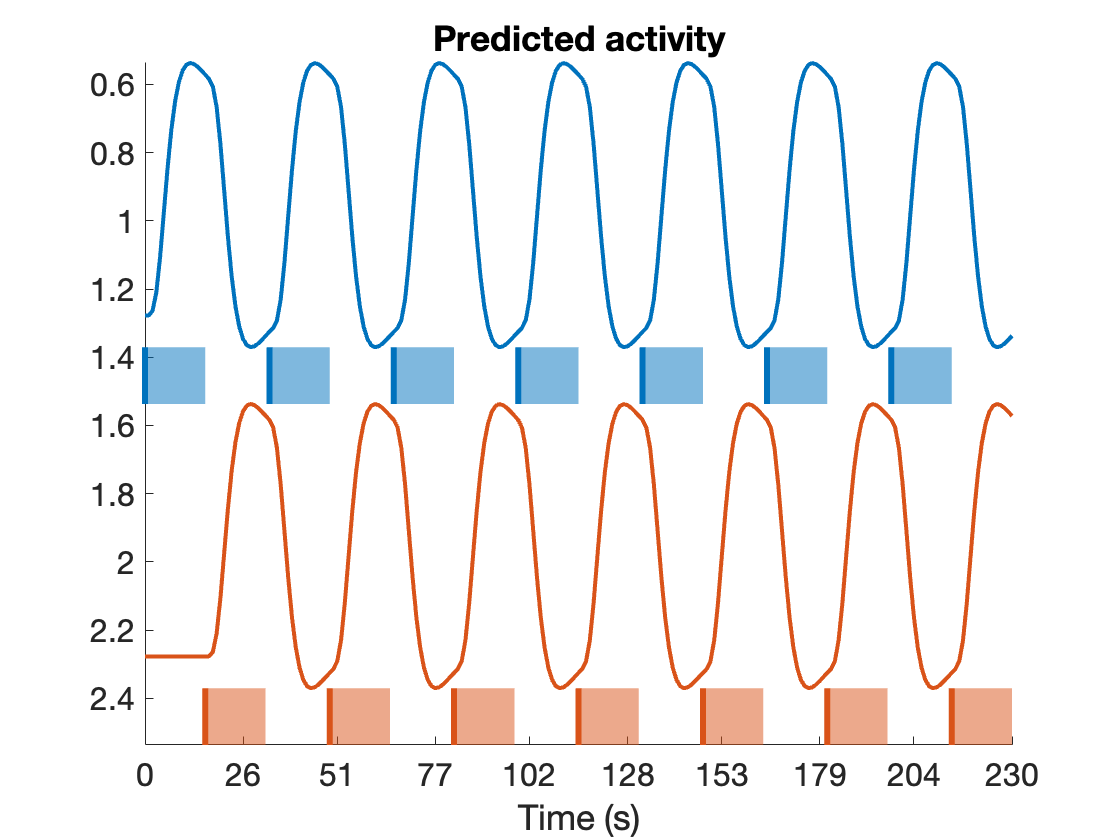

% optimizeGA, onsets2fmridesign, plotDesign, onsets2power, onsets2efficiency, onsets2singletrial
% create_block_design, create_design_single_event, create_random_er_design, create_random_onsets
% calcEfficiency
% tor_make_deconv_mtx3


% Create task regressor

nconditions = 2;
blockduration = 16;
HPlength = 128;
scanlength = 230;

create_figure('Design');
[X, e] = create_block_design(scanlength, TR, nconditions, blockduration, Inf, false);


Xc = scale(X) * [.5 -.5 0]';

corr(X(:, 1), Xc)

ans = 0.9889

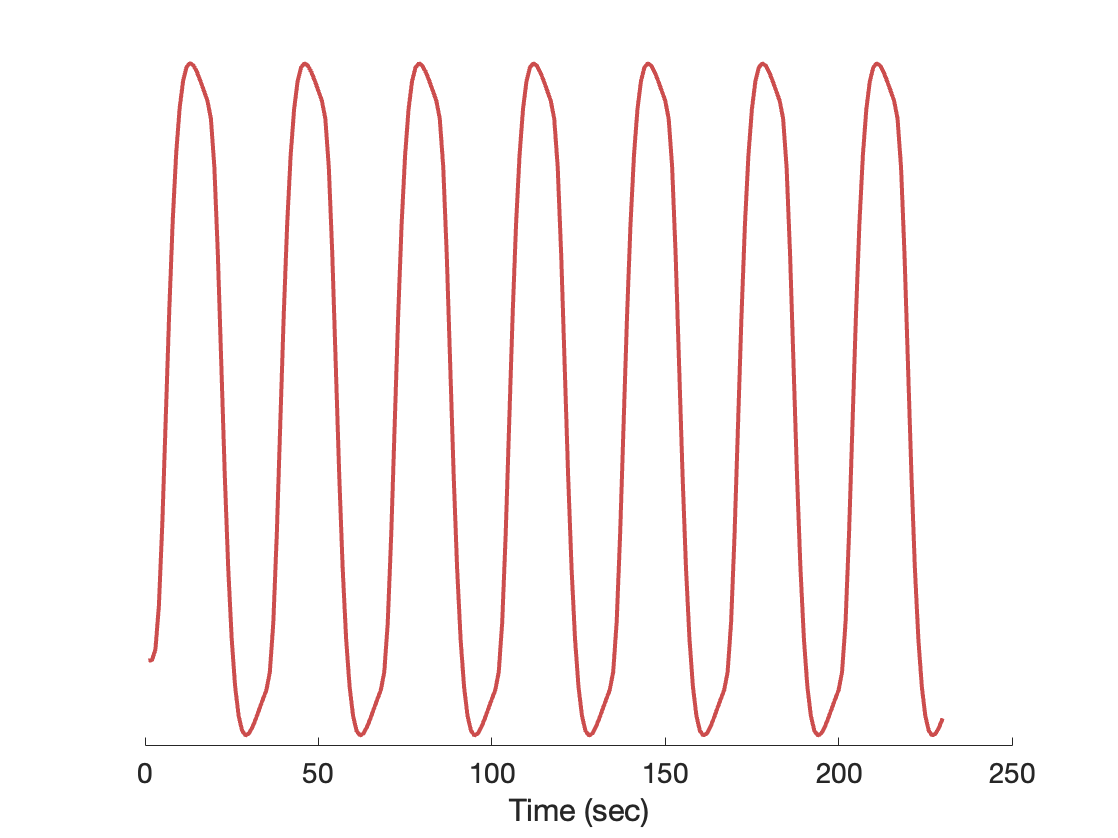


X = 1 .* X(:, 1) ./ max(X(:, 1));  % task regressor - single block

create_figure('Design2');
plot(X, 'Color', [.8 .3 .3], 'LineWidth', 2);
xlabel('Time (sec)')
set(gca, 'YColor', 'none')
set(gca, 'FontSize', 14)

% High-pass filter
[S, KL, KH] = use_spm_filter(TR, scanlength, 'none', 'specify', HPlength);

[X_filtered, I, S] = hpfilter(X, TR, HPlength, scanlength);

create_figure('Filter', 1, 2)

ans =   Figure (Filter) with properties:

      Number: 9
        Name: 'Filter'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


imagesc(KH); set(gca, 'YDir', 'Reverse'); colormap bone

subplot(1, 2, 2); hold on;
max_freq = [];
k = size(KH, 2);

% FFT plot of filter

for i = 1:k

    [myfft, freq, line_handle, nyquist_line_handle, max_freq(i)] = fft_calc(repmat(KH(:, i), 10, 1), TR);
    set(line_handle, 'Color', 'k')

end

disp('Filter frequencies')

Filter frequencies


max_freq

max_freq =     0.0043    0.0043    0.0087    0.0087    0.0130


1./max_freq

ans =   230.0000  230.0000  115.0000  115.0000   76.6667


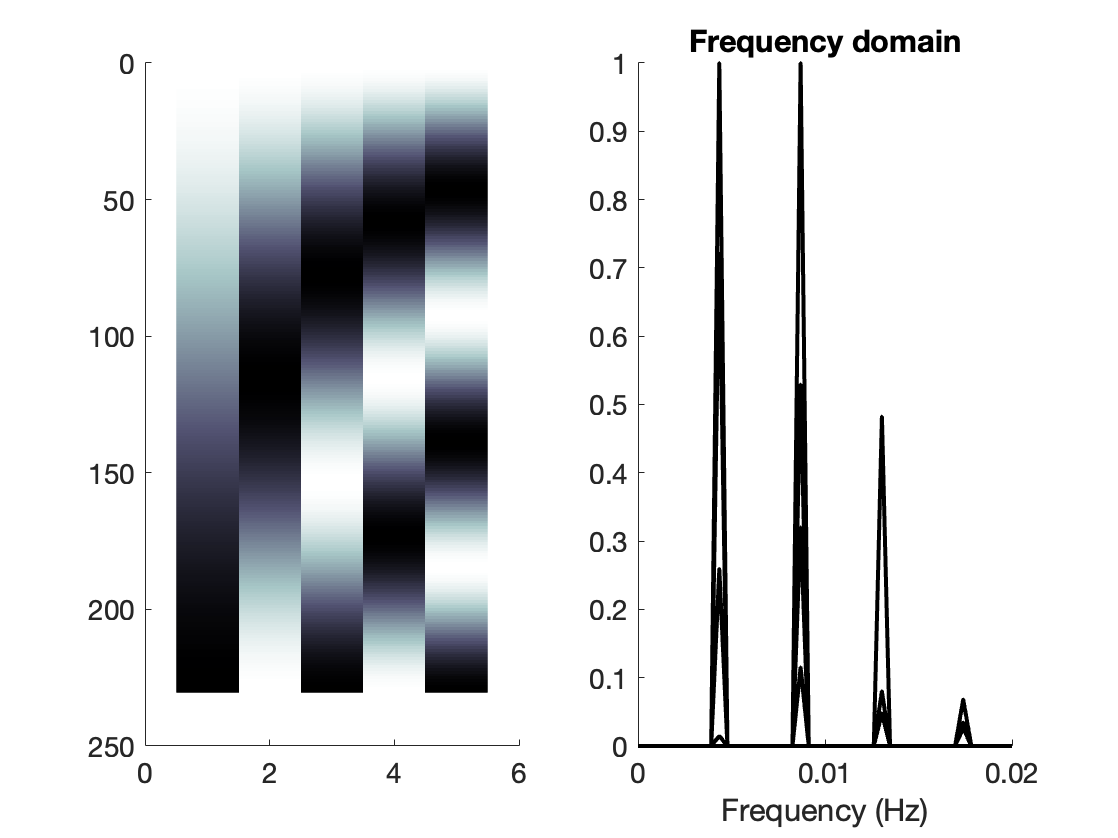

set(gca, 'XLim', [0 1/50])

% Simulate drift with filter

k = size(KH, 2);

create_figure('simulated drift', 2, 1)

ans =   Figure (simulated drift) with properties:

      Number: 27
        Name: 'simulated drift'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


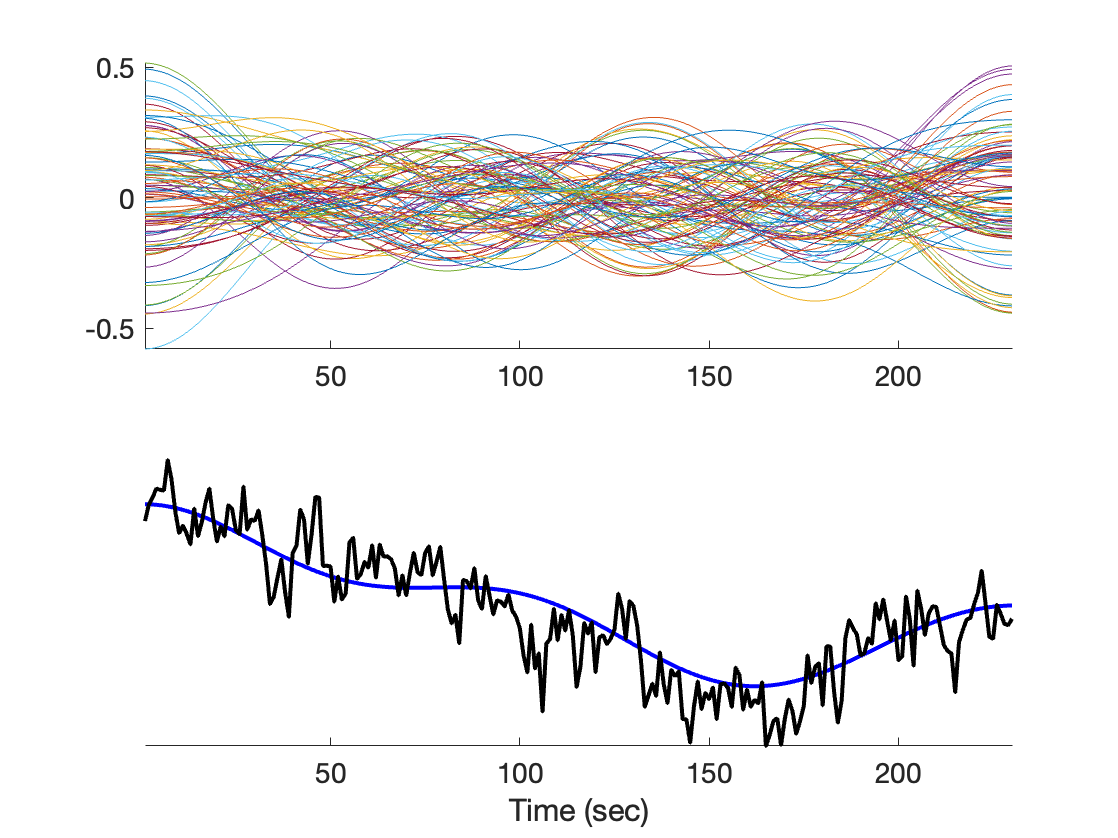


xx =  1 ./ (1:k)';  % exponential weights, decreasing with frequency

for i = 1:100

    eta = randn(k, 1);
    w = sign(eta) .* abs(eta) .^ xx;

    noisevec = KH * w;

    plot(noisevec);

end
axis tight

subplot(2, 1, 2)
w = [1 .5 -.25 .4 .1 ]';
slow_drift = 2 + 2 .* scale(KH * w);

plot(slow_drift, 'b', 'LineWidth', 2);
axis tight

noisevec = slow_drift + noise_arp(scanlength);
plot(noisevec, 'k', 'LineWidth', 2);
xlabel('Time (sec)')
set(gca, 'YColor', 'none')
set(gca, 'FontSize', 14)


create_figure('FFT')

ans =   Figure (FFT) with properties:

      Number: 4
        Name: 'FFT'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


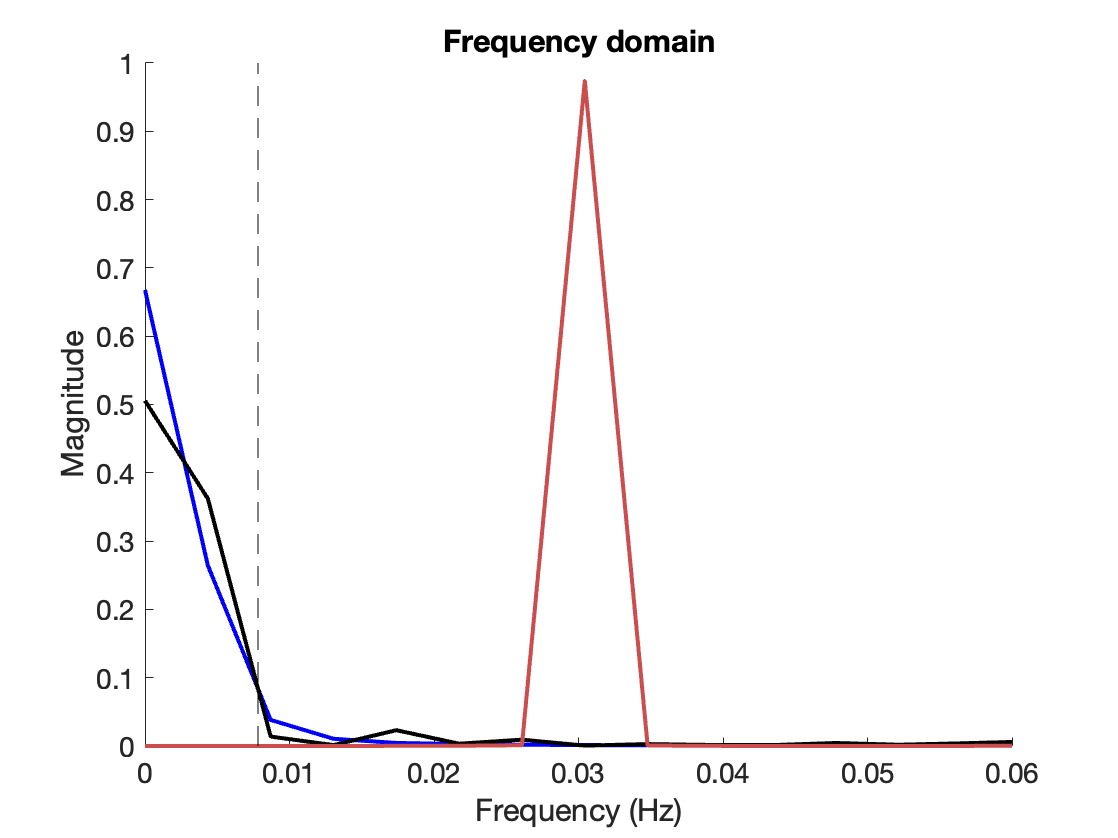


[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(slow_drift, TR);
set(line_handle, 'Color', 'b')

[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(noisevec, TR);
set(line_handle, 'Color', 'k')

[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(X, TR);
set(line_handle, 'Color', [.8 .3 .3])
set(gca, 'XLim', [0 0.06])
ylabel('Magnitude')
set(gca, 'FontSize', 14)

hh = plot_vertical_line(1/HPlength);
set(hh, 'LineStyle', '--');

% Signal

y = noisevec + X;
create_figure('Signal')

ans =   Figure (Signal) with properties:

      Number: 30
        Name: 'Signal'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


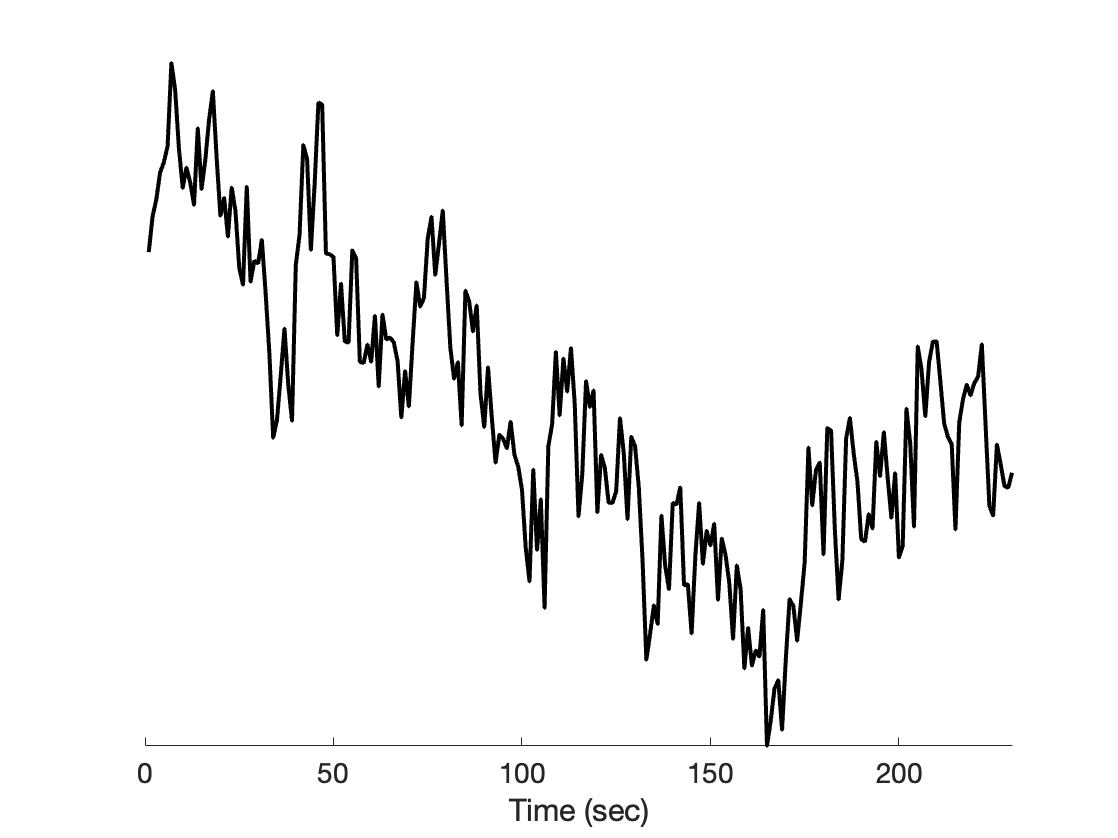

plot(y, 'k', 'LineWidth', 2);
xlabel('Time (sec)')
set(gca, 'YColor', 'none')
set(gca, 'FontSize', 14)
axis tight
set(gca, 'XLim', [0 230])


% re-plot noise
create_figure('Noise')

ans =   Figure (Noise) with properties:

      Number: 35
        Name: 'Noise'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


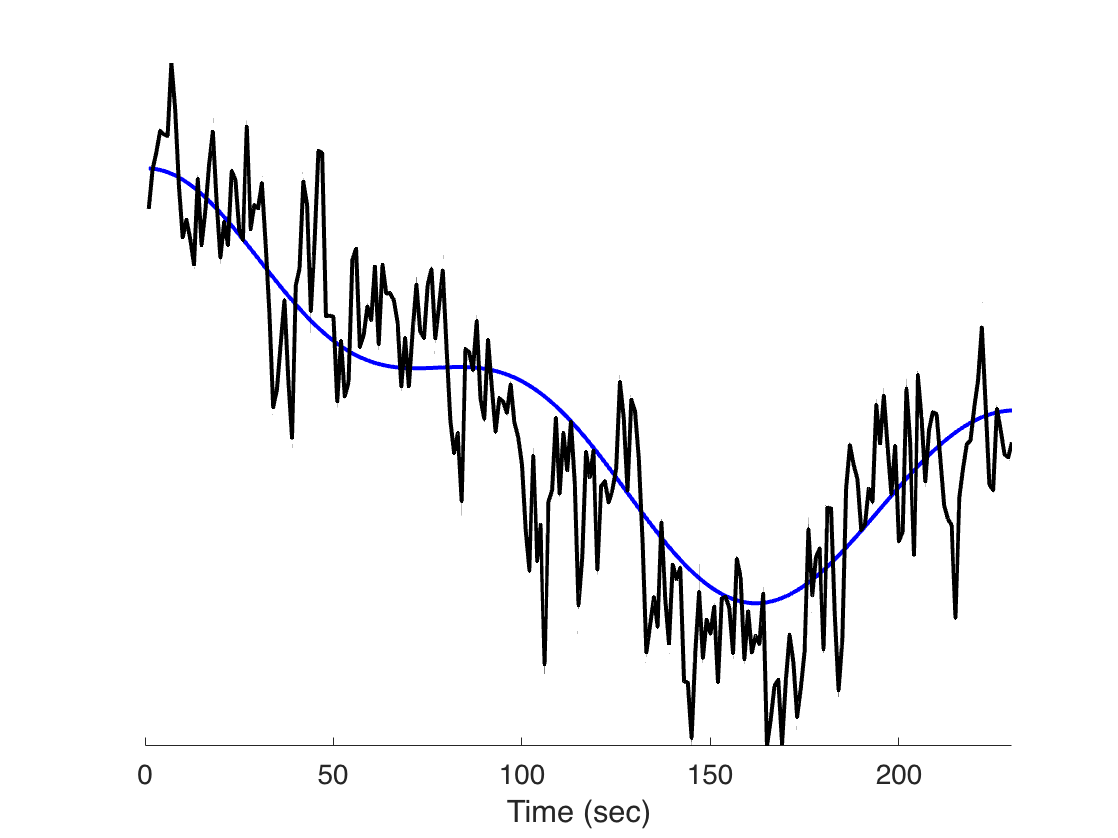

plot(slow_drift, 'b', 'LineWidth', 2);
plot(noisevec, 'k', 'LineWidth', 2);
xlabel('Time (sec)')
set(gca, 'YColor', 'none')
set(gca, 'FontSize', 14)
axis tight
set(gca, 'XLim', [0 230])

% Design matrix and fit

XX = [X./4 ones(scanlength, 1)./5 KH];

b = pinv(XX) * y;

fit_task = XX(:, [1 2]) * b([1 2]);
fit_drift = XX(:, [2:end]) * b([2:end]);
fit_all = XX(:, :) * b(:);

% re-plot y and fits
create_figure('y fit', 2, 1)

ans =   Figure (y fit) with properties:

      Number: 37
        Name: 'y fit'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


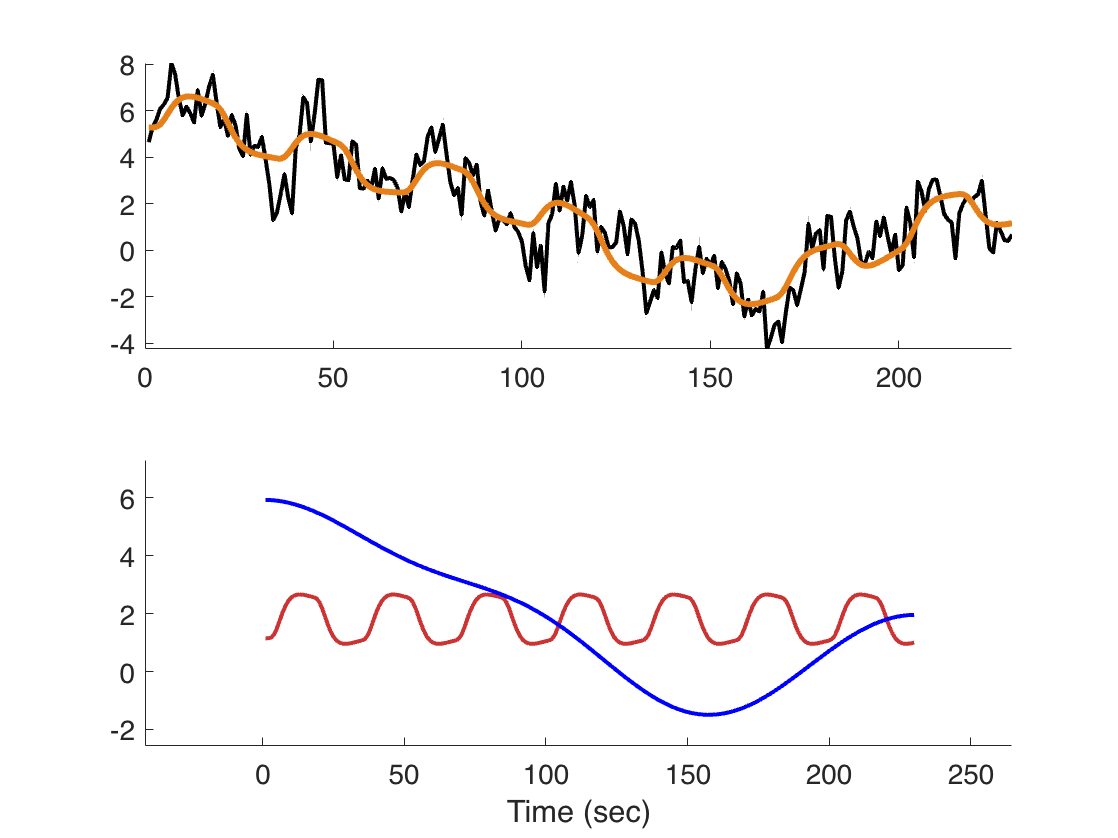

plot(y, 'k', 'LineWidth', 2);
plot(fit_all, 'Color', [.9 .5 .1], 'LineWidth', 3);
set(gca, 'FontSize', 14)
axis tight
set(gca, 'XLim', [0 230])

subplot(2, 1, 2)
plot(fit_task, 'Color', [.8 .2 .2], 'LineWidth', 2);
plot(fit_drift, 'Color', 'b', 'LineWidth', 2);
xlabel('Time (sec)')
% set(gca, 'YColor', 'none')
set(gca, 'FontSize', 14)
axis tight
set(gca, 'XLim', [0 230])


% Design
create_figure('Design')

ans =   Figure (Design) with properties:

      Number: 11
        Name: 'Design'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


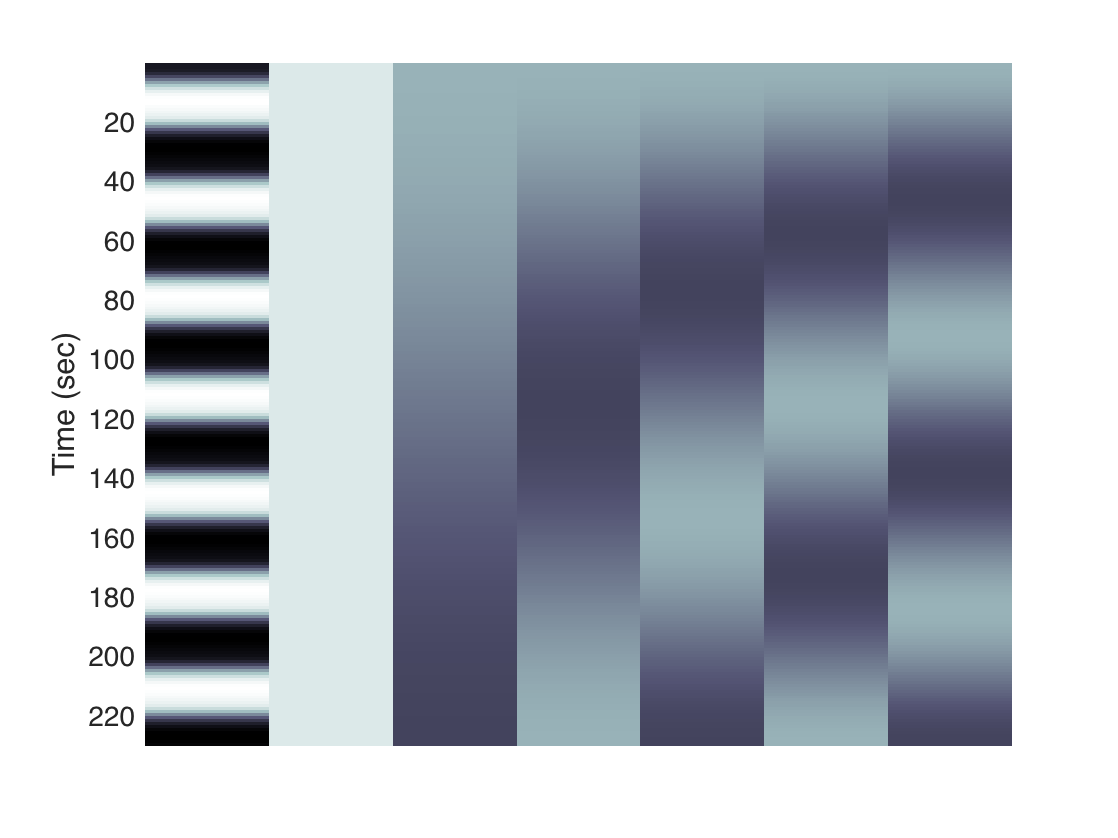

imagesc(XX); 
set(gca, 'YDir', 'Reverse', 'XColor', 'none'); axis tight; colormap bone
ylabel('Time (sec)')

## Filtering and aliasing with an event-related design

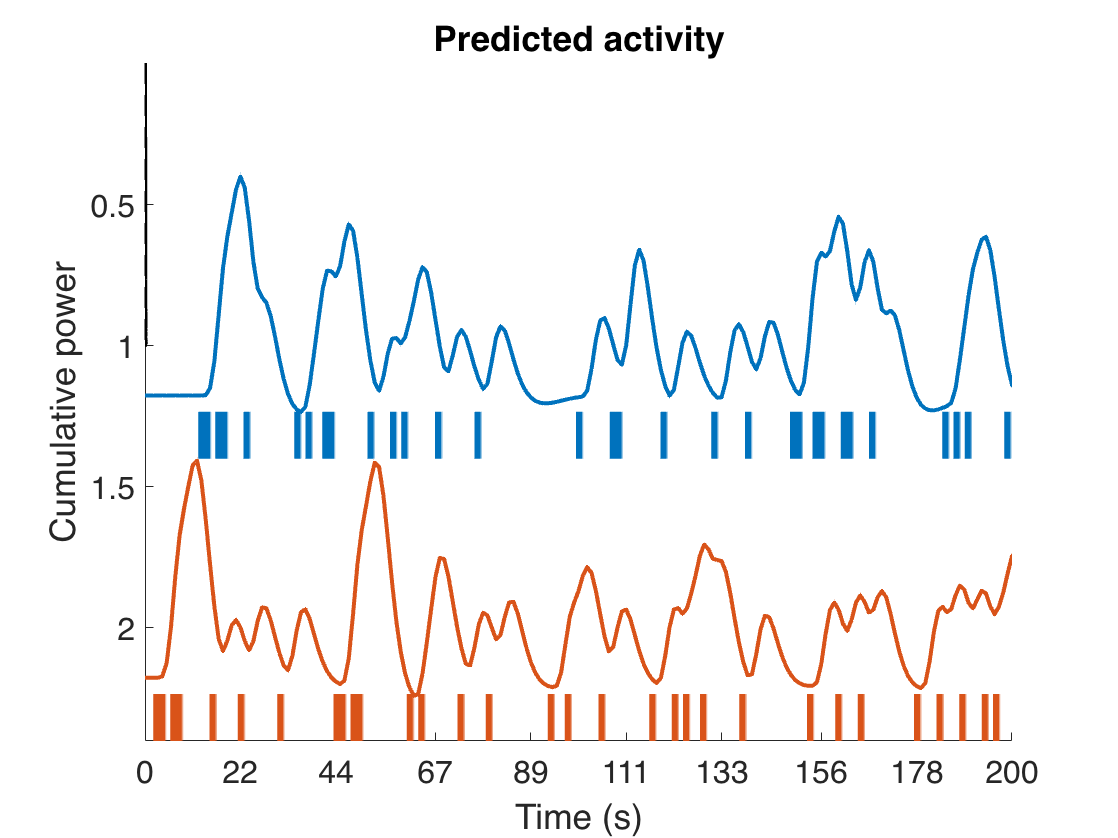

TR = 1;
ISI = 1.3;
HPlength = 60;

[X, e, onsets] = create_random_er_design(TR, ISI, 1, [.2 .2], Inf, 0);

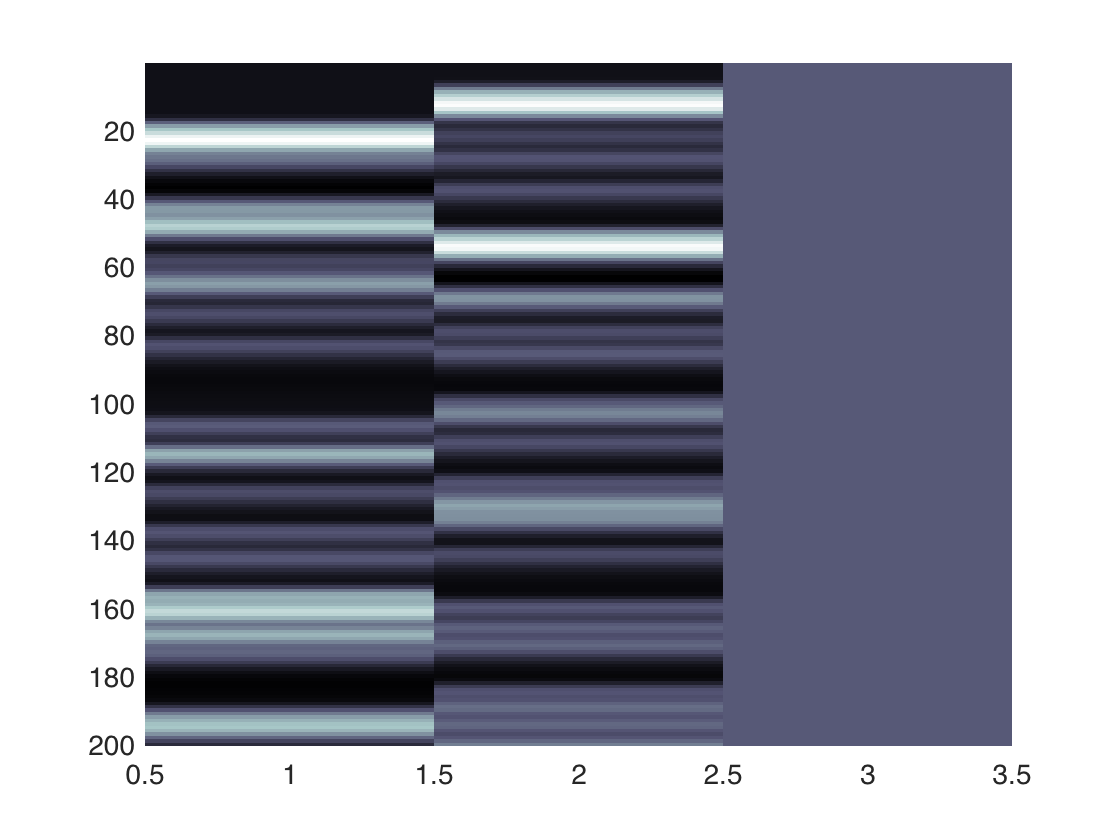


create_figure('X'); imagesc(X); set(gca, 'YDir', 'Reverse'); axis tight; colormap bone

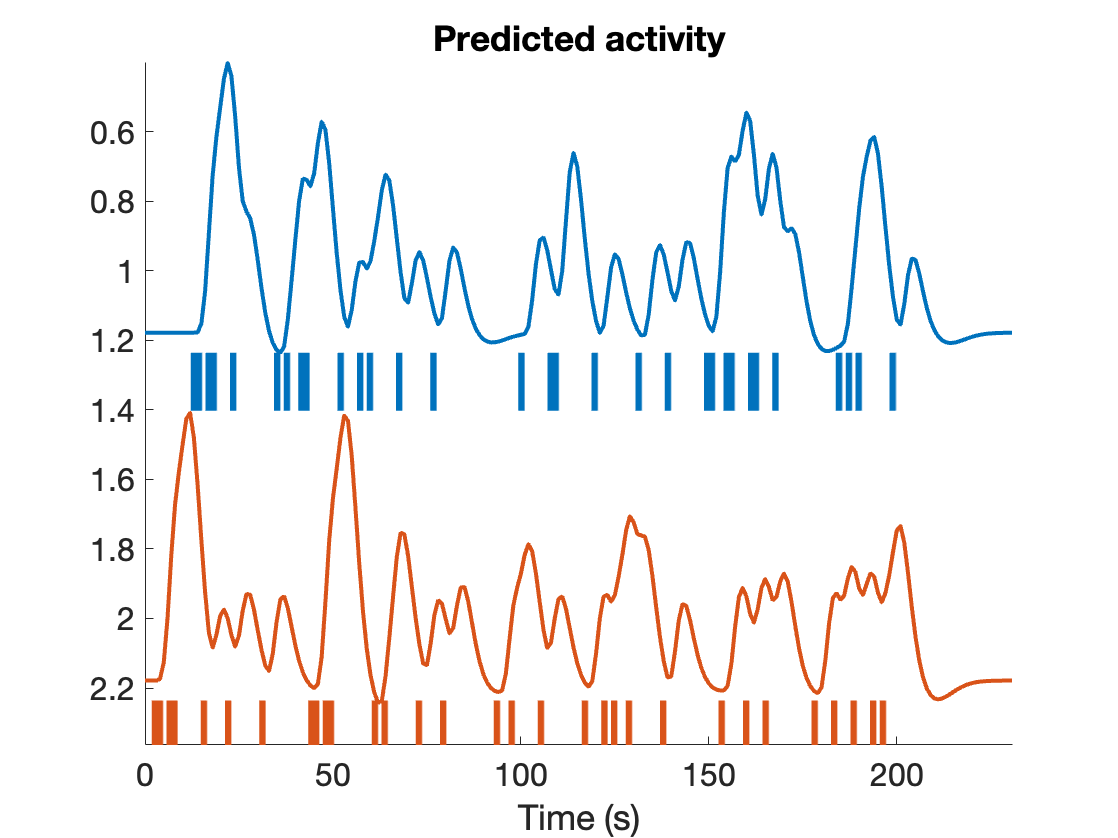



[~,~,out,handles] = plotDesign(onsets,[],TR);
colors = {get(handles(1), 'Color')  get(handles(2), 'Color') [.9 .7 0]};
set(gca, 'XLim', [0 size(X, 1)])

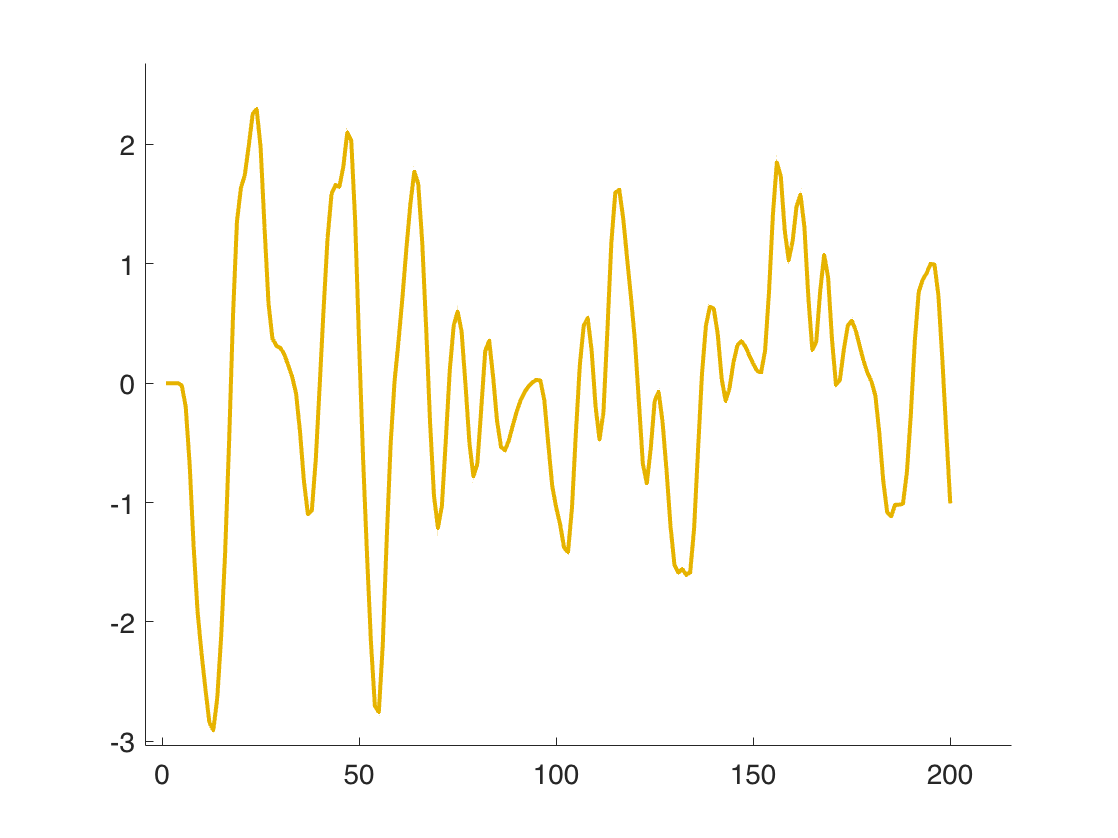


create_figure('Contrast');
C = X(:, 1) - X(:, 2);
plot(C, '-', 'Color', colors{3}, 'LineWidth', 2); 
axis tight; 
set(gca, 'XLim', [0 size(X, 1)])


create_figure('FFT')

ans =   Figure (FFT) with properties:

      Number: 4
        Name: 'FFT'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


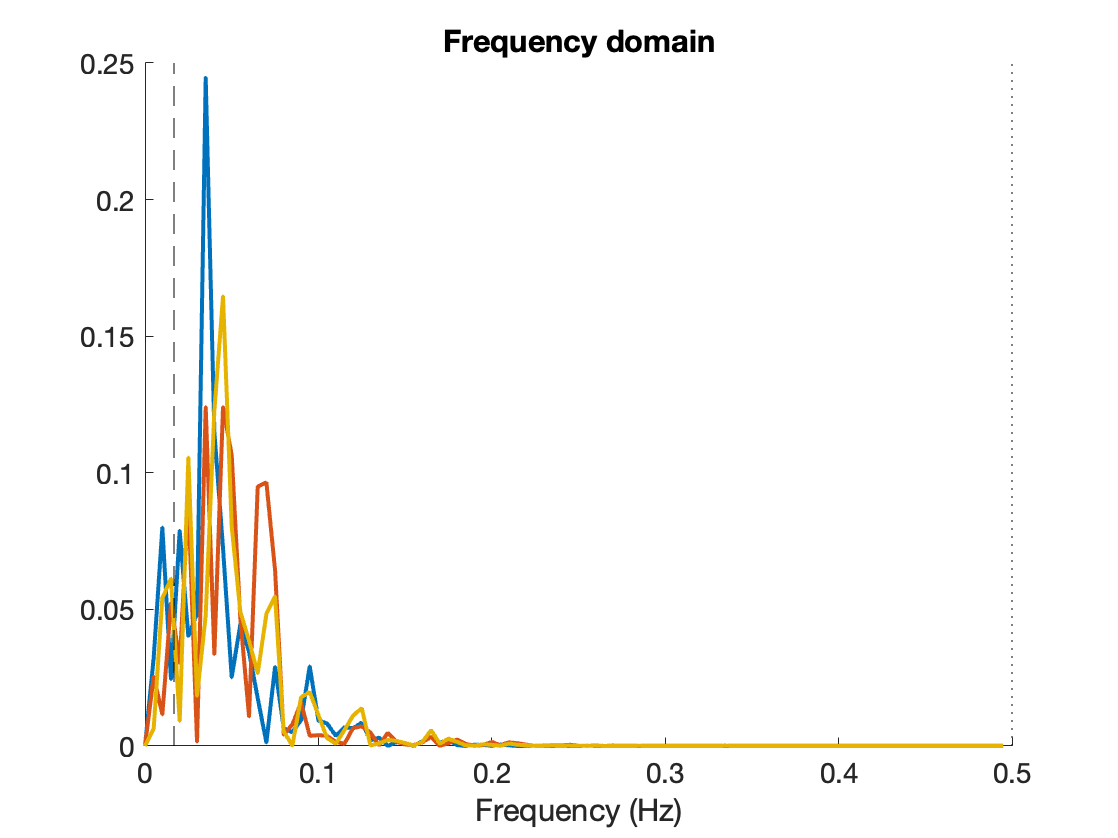


[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(scale(X(:, 1), 1), TR);
set(line_handle, 'Color', colors{1})

[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(scale(X(:, 2), 1), TR);
set(line_handle, 'Color', colors{2})

[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(scale(C, 1), TR);
set(line_handle, 'Color', colors{3})

hh = plot_vertical_line(1/HPlength);
set(hh, 'LineStyle', '--');

set(gca, 'XLim', [0 0.2])


cum_freq = cumsum(myfft);

create_figure('Cum Freq')

ans =   Figure (Cum Freq) with properties:

      Number: 46
        Name: 'Cum Freq'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


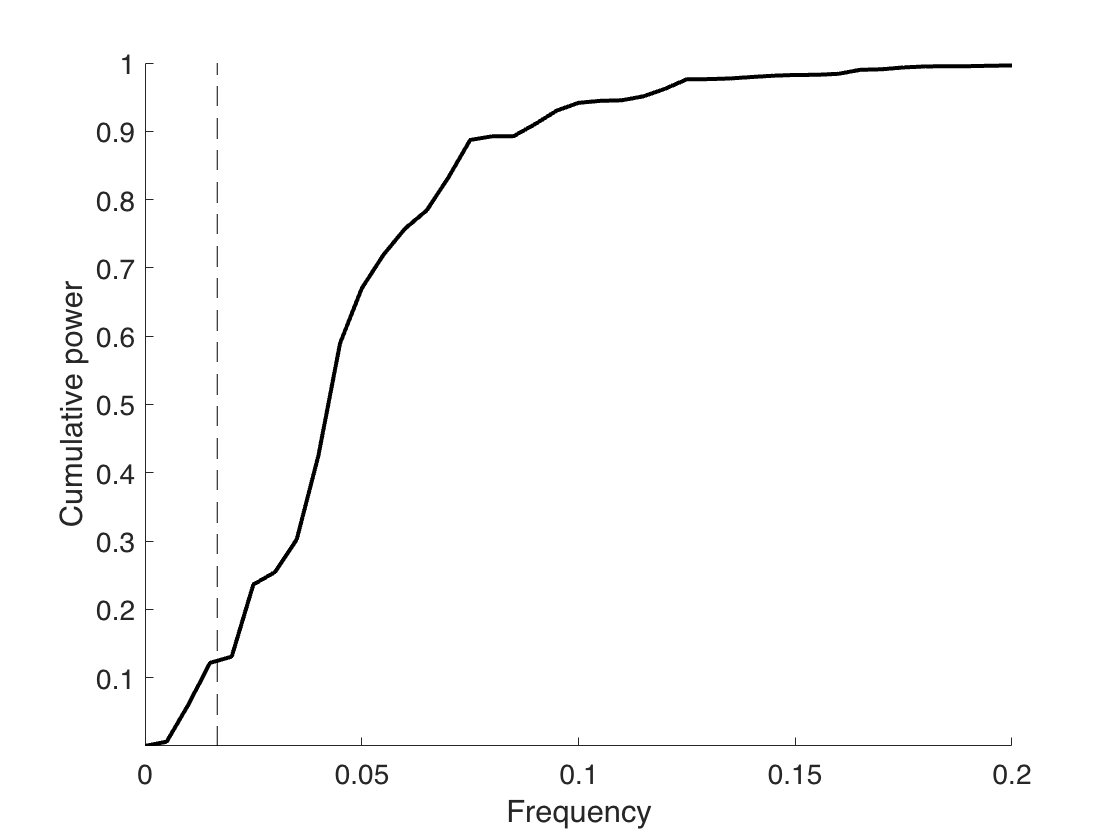

plot(freq, cum_freq, 'k-', 'LineWidth', 2)
axis tight;
xlabel('Frequency')
ylabel('Cumulative power')

hh = plot_vertical_line(1/HPlength);
set(hh, 'LineStyle', '--');
set(gca, 'XLim', [0 0.2])


% Find Proportion of power lost 
wh = max(find(freq <= 1/HPlength));
power_lost = max(cum_freq(1:wh))

power_lost = 0.1217

% hh = plot_horizontal_line(power_lost);
% set(hh, 'LineStyle', '--');


% Filter design and assess loss of variance

Xf = hpfilter(X, TR, HPlength, size(X, 1));

Cf = hpfilter(C, TR, HPlength, size(X, 1));


create_figure('FFT')

ans =   Figure (FFT) with properties:

      Number: 4
        Name: 'FFT'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


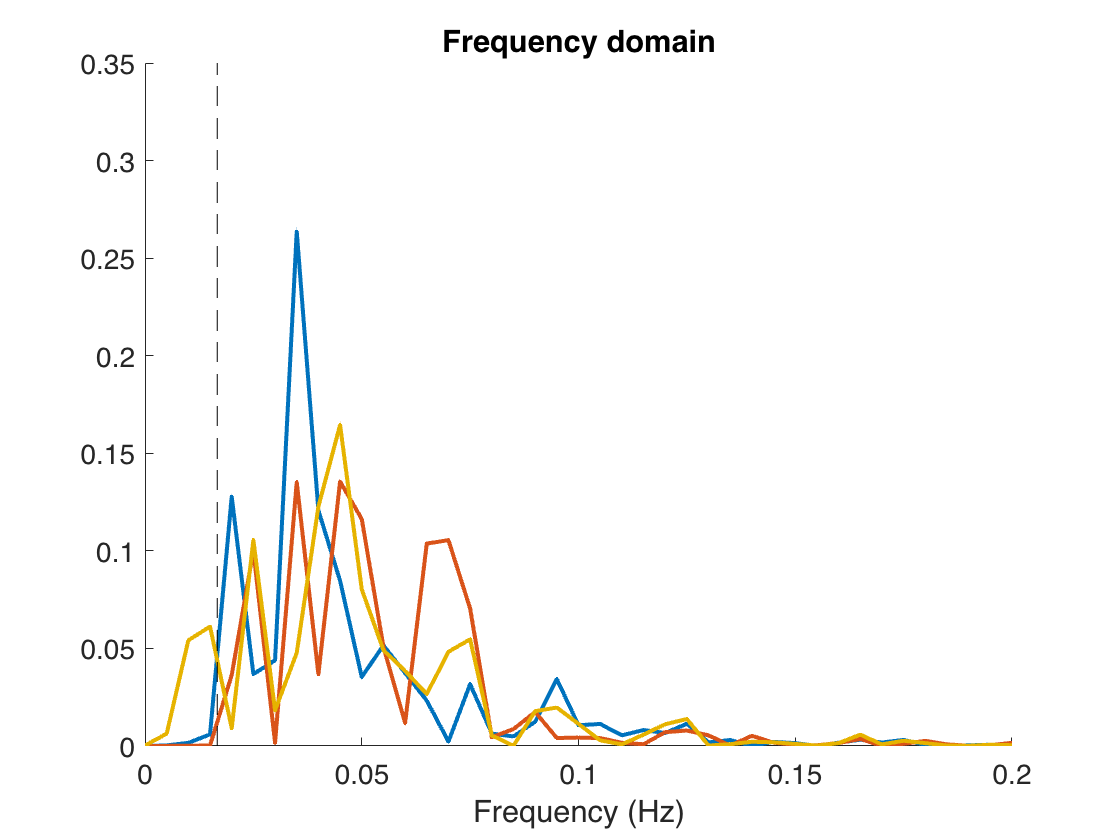


[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(scale(Xf(:, 1), 1), TR);
set(line_handle, 'Color', colors{1})

[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(scale(Xf(:, 2), 1), TR);
set(line_handle, 'Color', colors{2})

[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(C, TR);
set(line_handle, 'Color', colors{3})

hh = plot_vertical_line(1/HPlength);
set(hh, 'LineStyle', '--');
set(gca, 'XLim', [0 0.2])

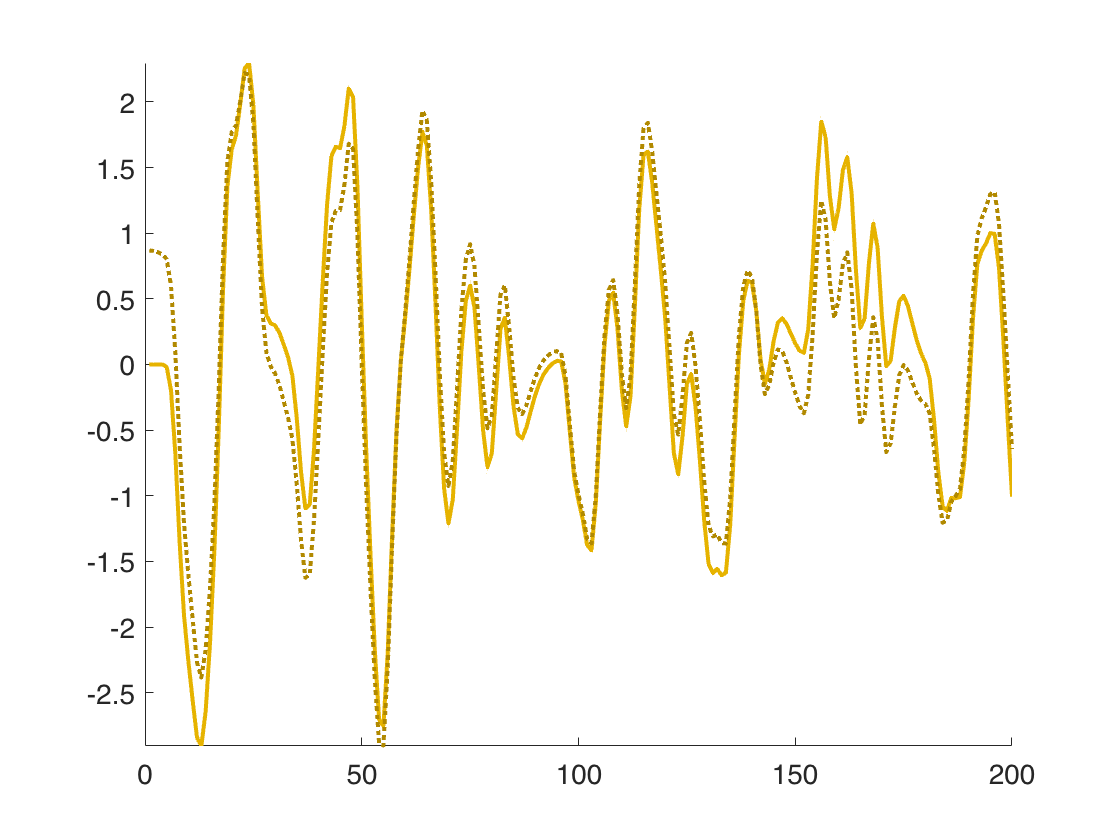



create_figure('Contrast');
plot(C, '-', 'Color', colors{3}, 'LineWidth', 2); 
plot(Cf, ':', 'Color', colors{3} ./ 1.3, 'LineWidth', 2); 
axis tight; 
set(gca, 'XLim', [0 size(X, 1)])



cum_freq = cumsum(myfft);

create_figure('Cum Freq')

ans =   Figure (Cum Freq) with properties:

      Number: 46
        Name: 'Cum Freq'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


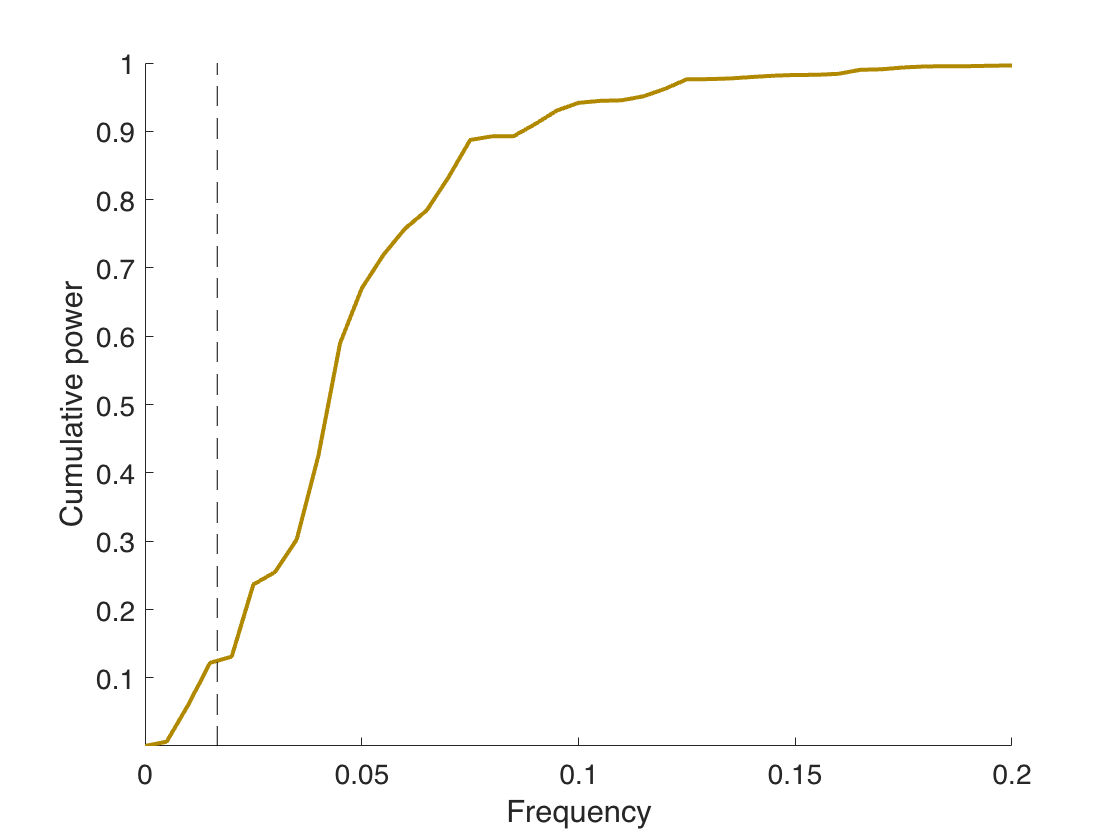

plot(freq, cum_freq, 'Color', colors{3} ./ 1.3, 'LineWidth', 2)
axis tight;
xlabel('Frequency')
ylabel('Cumulative power')

hh = plot_vertical_line(1/HPlength);
set(hh, 'LineStyle', '--');
set(gca, 'XLim', [0 0.2])


% Find Proportion of power lost 
wh = max(find(freq <= 1/HPlength));
power_lost = max(cum_freq(1:wh))

power_lost = 0.1219

### Simulated heartbeat and aliasing

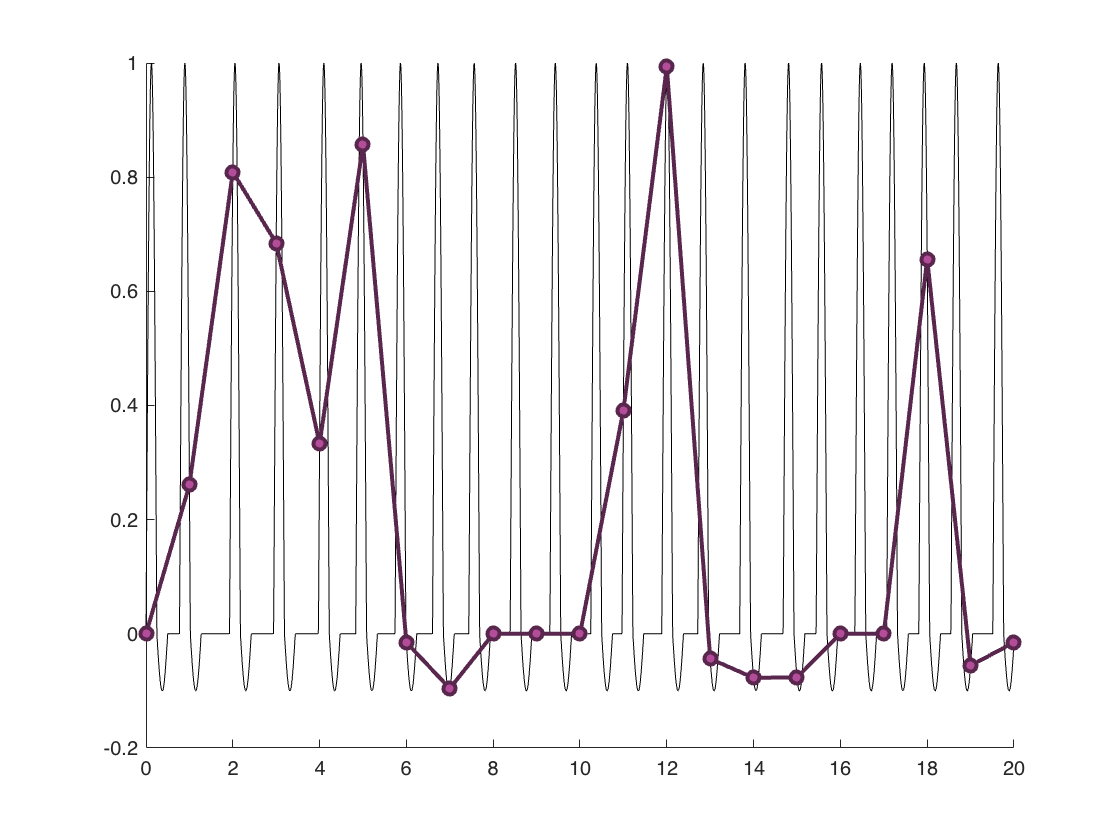


theta = 0;             % Phase, in radians
F = 2;               % Frequency of sin wave (cycles/sec)
T = 0.001;             % Time resolution in sec; time between high-frequency samples
scanlen = size(X, 1) .* TR;
t = 0:0.001:(scanlen-0.001);        % Vector of sample times for all samples (10 sec sampling duration)

tt = [0:T:0.5]';              % 1 sec / 1 beat, shift phase randomly

theta = 0 * rand(400, 1);
yy = {};

for i = 1:400

    yy{i} = sin(2 * pi * F * tt + theta(i));

    yy{i}(yy{i} < 0) = 0.1 * yy{i}(yy{i} < 0);  % make the undershoot small

    % yy{i} = [yy{i}; zeros(0.5/T, 1)]; % add 0.5 sec rest (IBI)

    yy{i} = [yy{i}; zeros(round(unifrnd(0.2, 0.7)/T), 1)]; % add 0.5 plus/minus sec rest (variable IBI)

end
y = cat(1, yy{:});
y = y(1:length(t));

figure; hold on; 
plot(t, y, 'k')
set(gca, 'XLim', [0 20])

plot(t(1:(TR/T):end), y(1:(TR/T):end), 'o-', 'LineWidth', 2, 'Color', [.7 .3 .6]./2, 'MarkerFaceColor', [.7 .3 .6])


xlabel('Time (sec)')



create_figure('FFT')

ans =   Figure (FFT) with properties:

      Number: 8
        Name: 'FFT'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


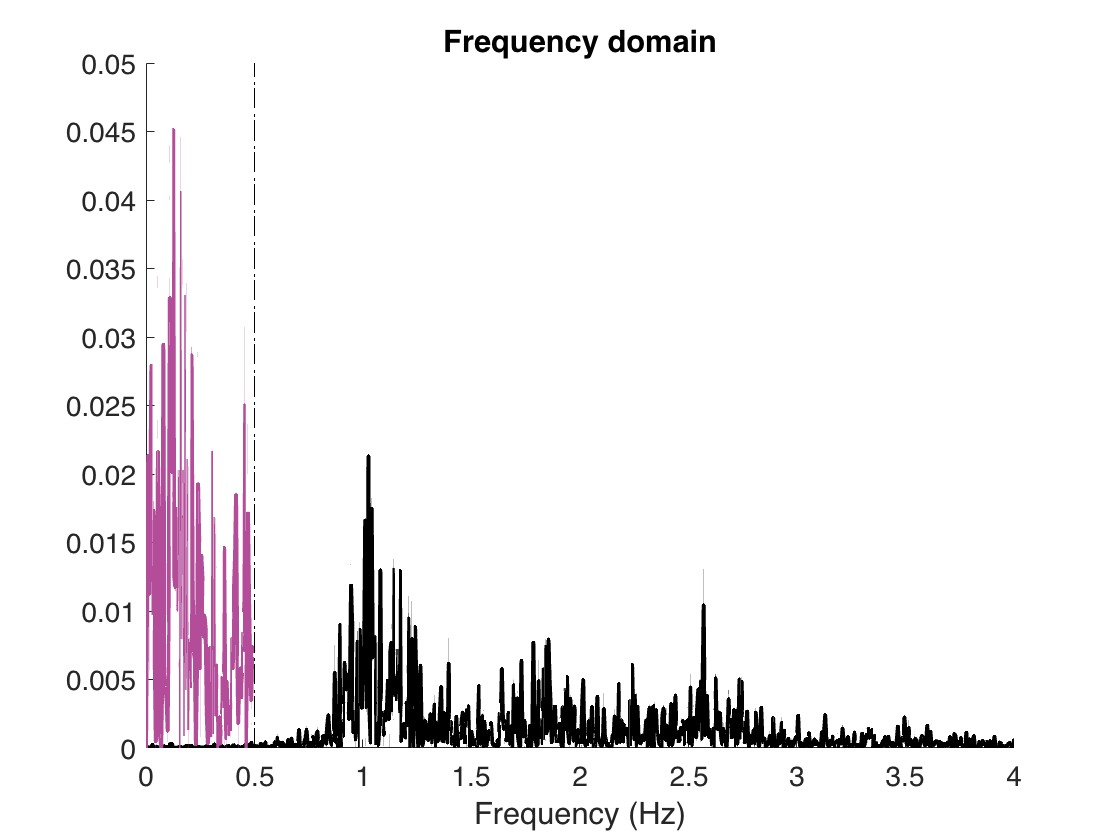


[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(scale(y, 1), T);
set(line_handle, 'Color', 'k')

[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(scale(y(1:(TR/T):end), 1), TR);
set(line_handle, 'Color', [.7 .3 .6])


hh = plot_vertical_line(1/(2*TR));
set(hh, 'LineStyle', '--');

set(gca, 'XLim', [0 4])

What sampling rate do you need to avoid aliasing?

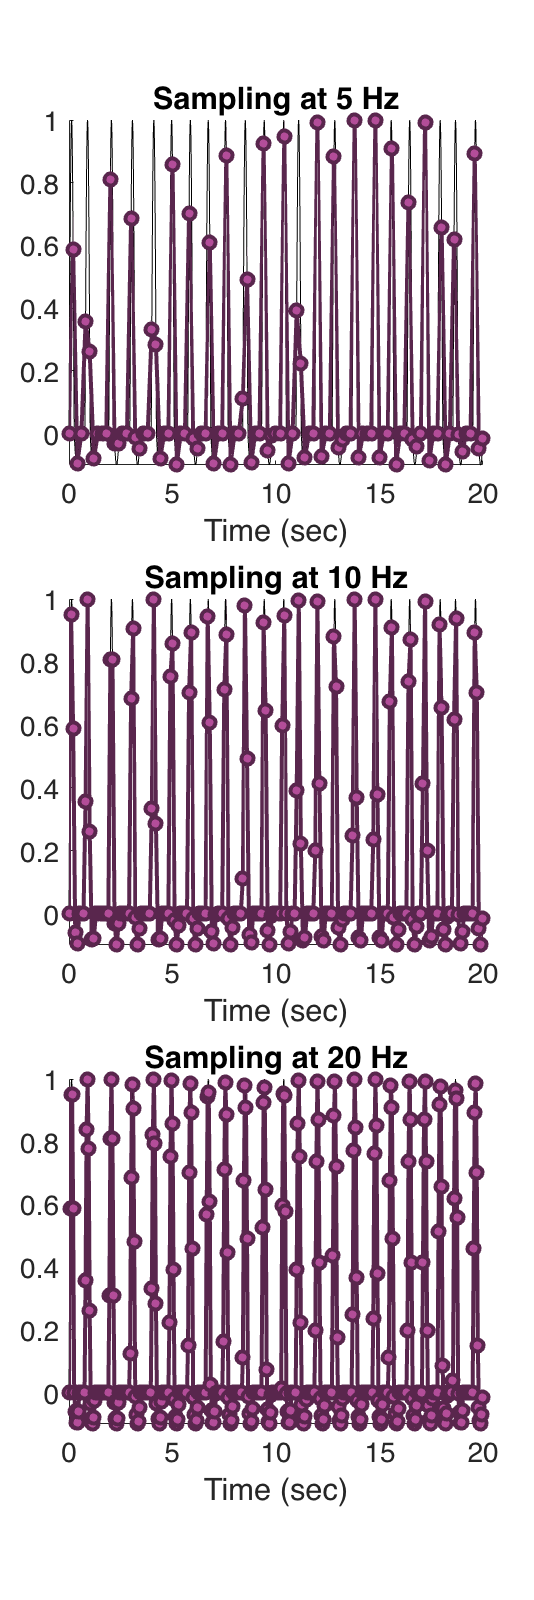


create_figure('heartbeat', 3, 1); hold on; 
plot(t, y, 'k')
set(gca, 'XLim', [0 20])
TR = 0.2; % 5 Hz
plot(t(1:(TR/T):end), y(1:(TR/T):end), 'o-', 'LineWidth', 2, 'Color', [.7 .3 .6]./2, 'MarkerFaceColor', [.7 .3 .6])
xlabel('Time (sec)')
title('Sampling at 5 Hz')

subplot(3, 1, 2)
plot(t, y, 'k')
set(gca, 'XLim', [0 20])
TR = 0.1; % 10 Hz
plot(t(1:(TR/T):end), y(1:(TR/T):end), 'o-', 'LineWidth', 2, 'Color', [.7 .3 .6]./2, 'MarkerFaceColor', [.7 .3 .6])
xlabel('Time (sec)')
title('Sampling at 10 Hz')

subplot(3, 1, 3)
plot(t, y, 'k')
set(gca, 'XLim', [0 20])
TR = 0.05; % 20 Hz
plot(t(1:(TR/T):end), y(1:(TR/T):end), 'o-', 'LineWidth', 2, 'Color', [.7 .3 .6]./2, 'MarkerFaceColor', [.7 .3 .6])
xlabel('Time (sec)')
title('Sampling at 20 Hz')

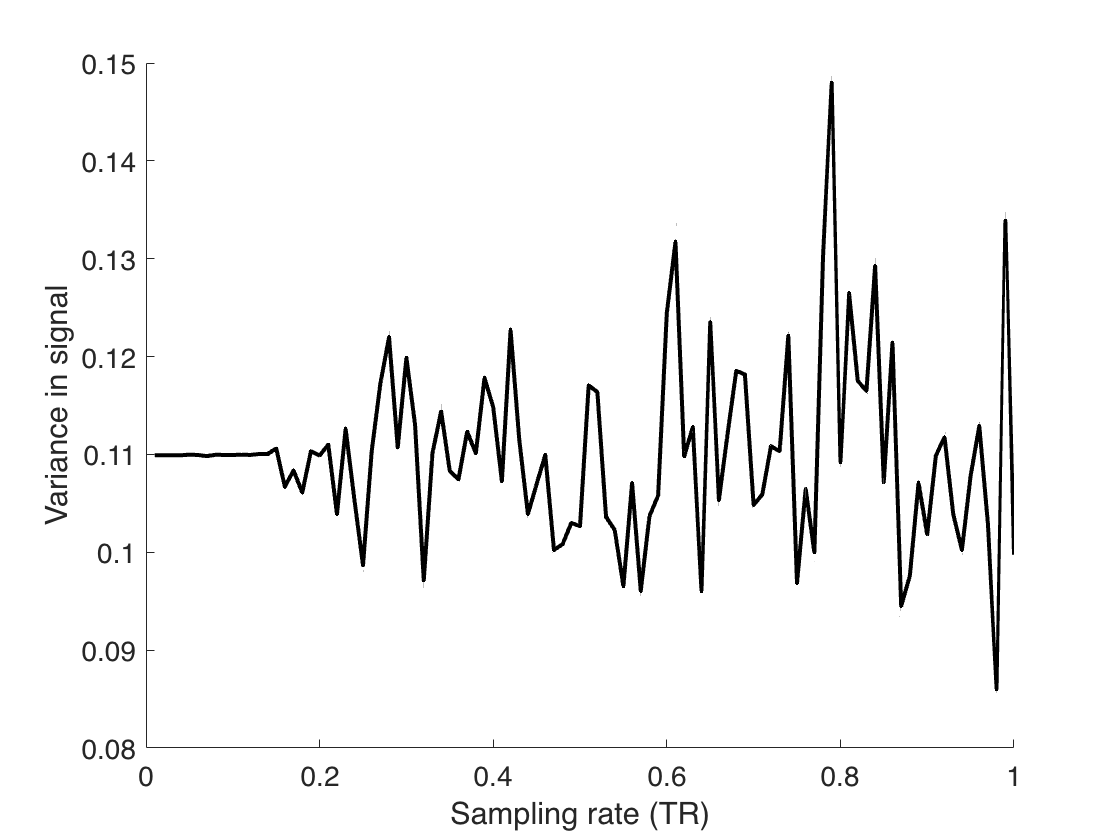


TR_vals = [0.01:0.01:1]';
signal_var = zeros(length(TR_vals), 1);

for i = 1:length(TR_vals)

    downsample_by = round(TR_vals(i)/T);
    signal_var(i) = var(y(1:downsample_by:end));

end

create_figure('Signal variance loss');
plot(TR_vals, signal_var, 'k', 'LineWidth', 2)
xlabel('Sampling rate (TR)')
ylabel('Variance in signal')

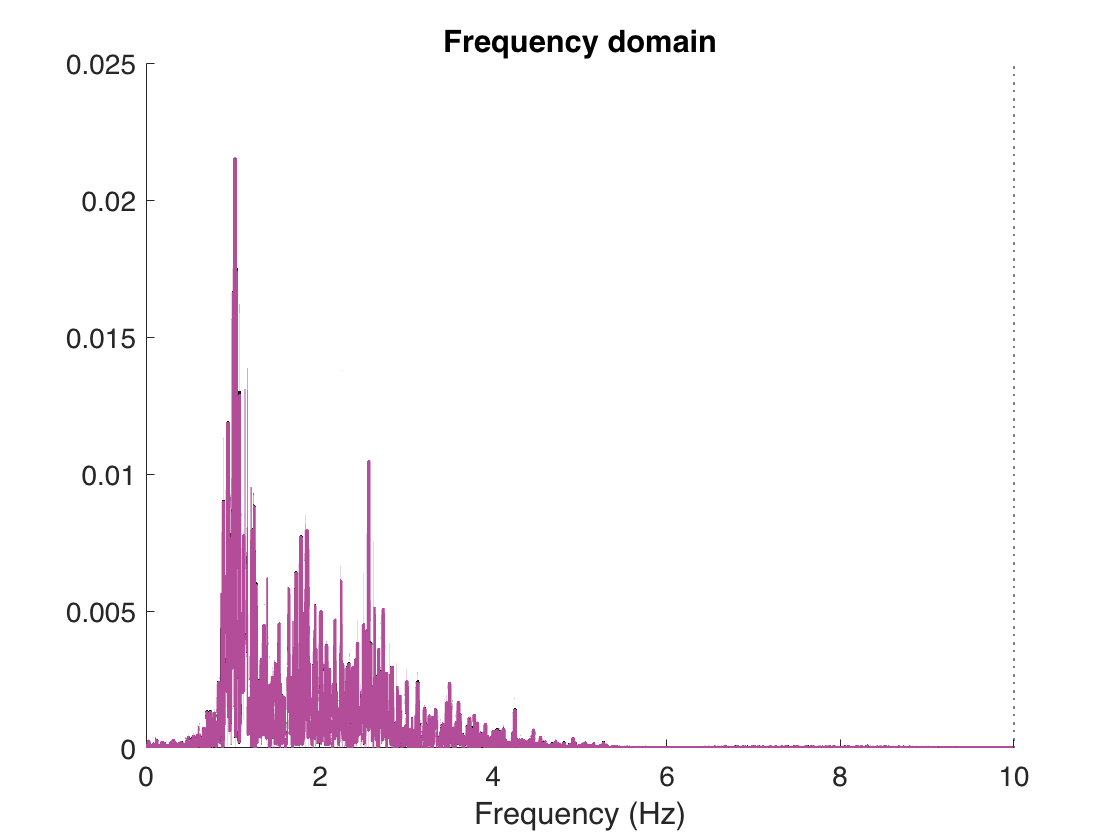



create_figure('cum FFT');

[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(scale(y, 1), T);
set(line_handle, 'Color', 'k')

set(gca, 'XLim', [0 10])

[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(scale(y(1:(TR/T):end), 1), TR);
set(line_handle, 'Color', [.7 .3 .6])

% 
% % 
% % hh = plot_vertical_line(1/(2*TR));
% % set(hh, 'LineStyle', '--');
% 
% cum_freq = cumsum(myfft);
% 
% create_figure('Cum Freq')
% plot(freq, cum_freq, 'Color', colors{3} ./ 1.3, 'LineWidth', 2)
% axis tight;
% xlabel('Frequency')
% ylabel('Cumulative power')
% 
% hh = plot_vertical_line(1/HPlength);
% set(hh, 'LineStyle', '--');
% set(gca, 'XLim', [0 0.6])
% 
% % Find Proportion of power lost 
% wh = max(find(freq <= 1/HPlength));
% power_lost = max(cum_freq(1:wh))




e = noise_arp(length(y));

downsample_by = round((1/T) / (1/TR))

downsample_by = 1000

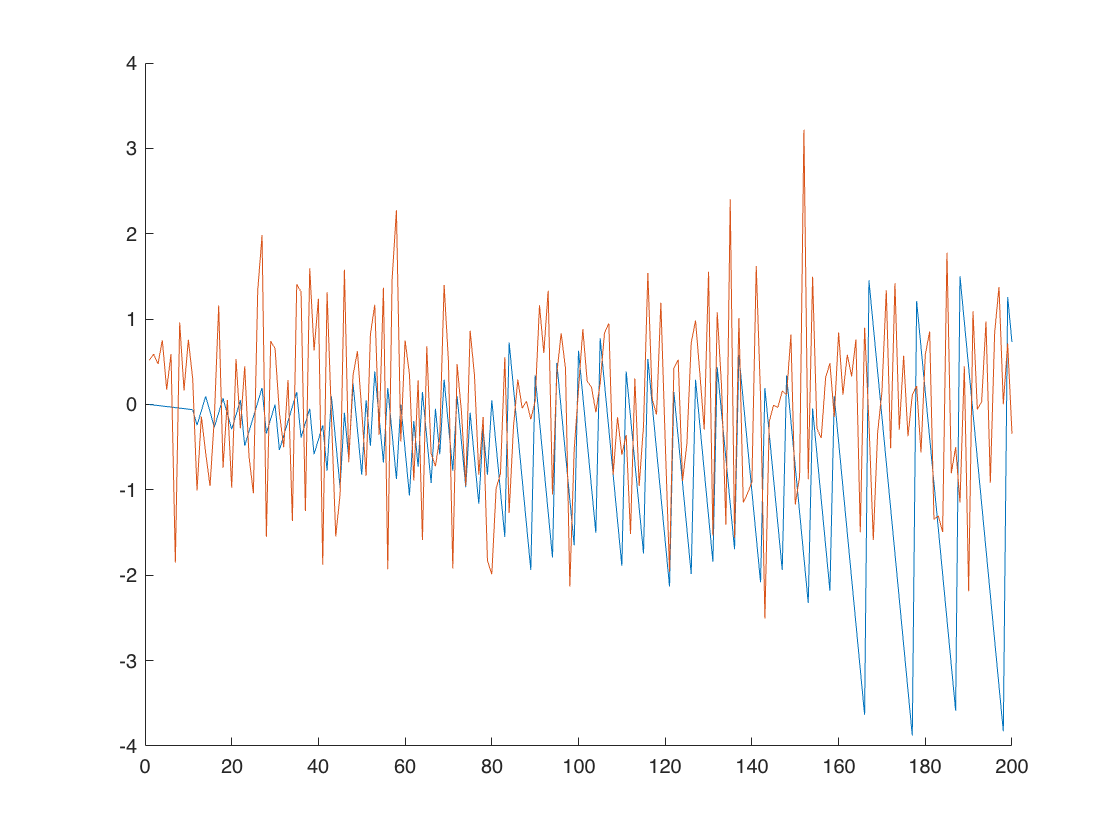


y_tr = y(1:downsample_by:end);
y_tr = y_tr' ./ std(y_tr);

e_tr = e(1:downsample_by:end);
e_tr = e_tr ./ std(e_tr);

figure; hold on; plot(y_tr); plot(e_tr)

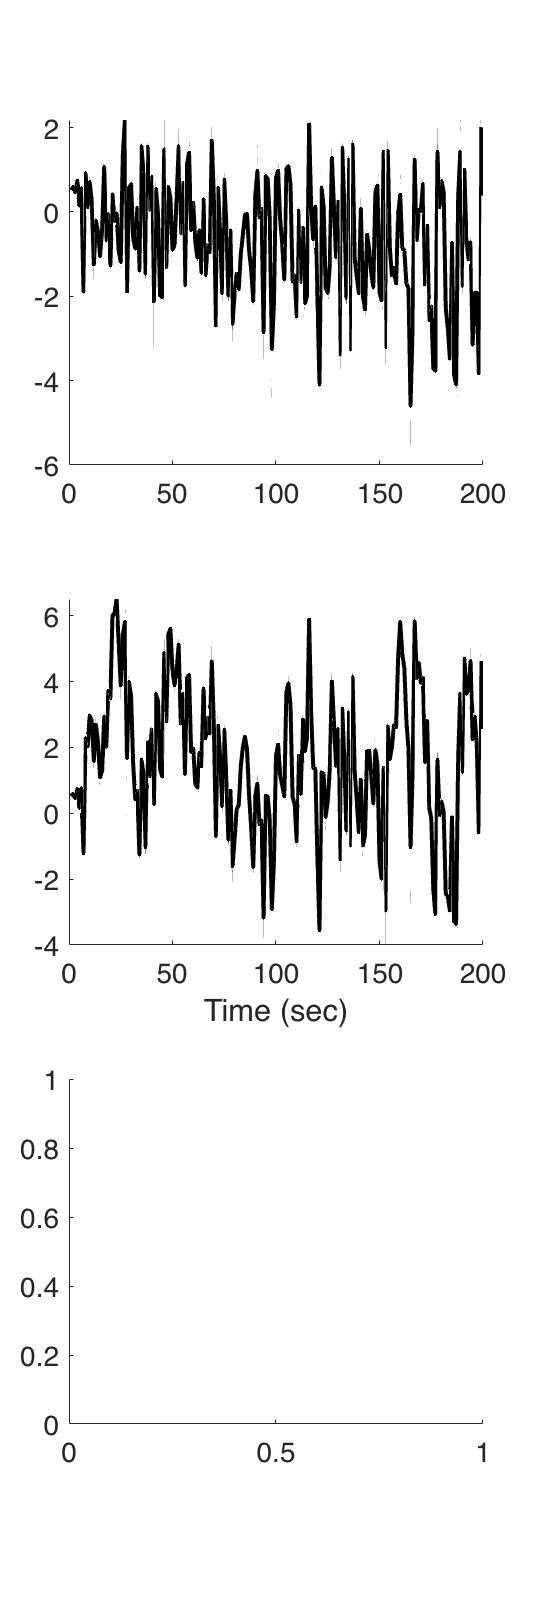


noisevec = y_tr + e_tr;

create_figure('signal and noise', 3, 1); hold on; set(gca, 'FontSize', 14)
plot(noisevec, 'k', 'LineWidth', 2)

subplot(3, 1, 2); set(gca, 'FontSize', 14)
datavec = 2 .* X(:, 1) + 1 * X(:, 2) + noisevec;

plot(datavec, 'k', 'LineWidth', 2)
xlabel('Time (sec)')


create_figure('fft')

ans =   Figure (fft) with properties:

      Number: 3
        Name: 'fft'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


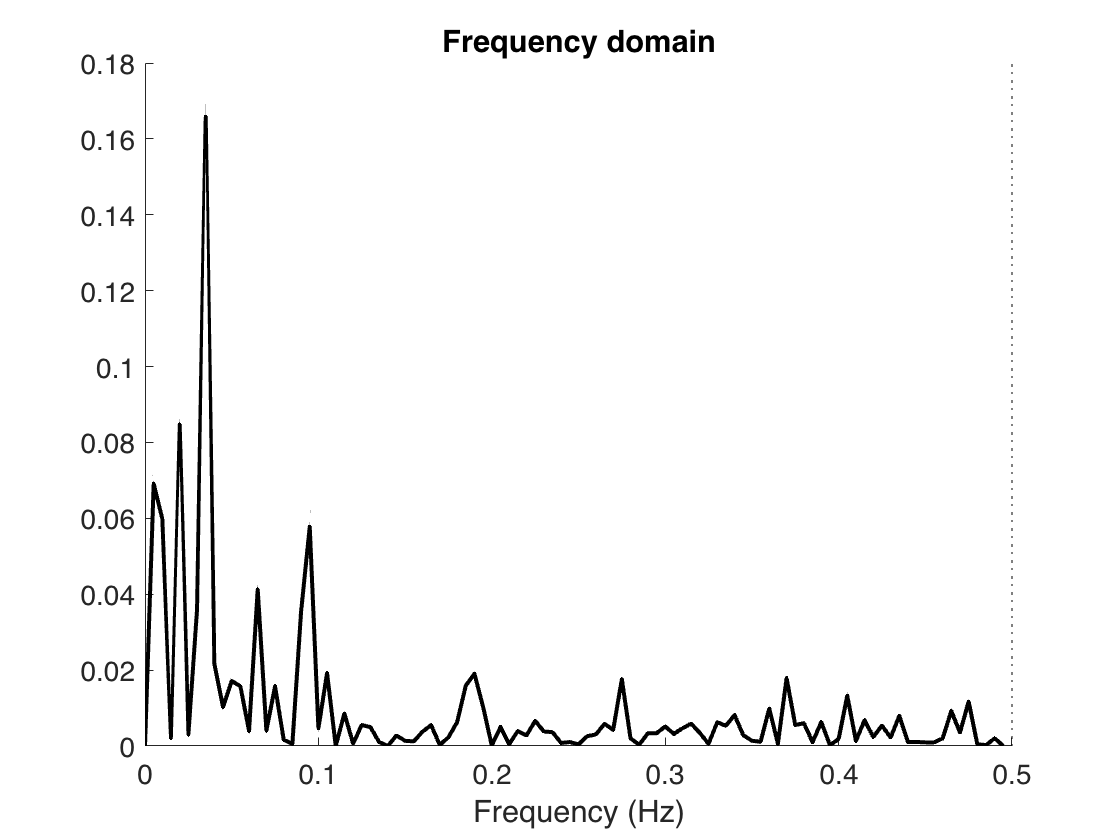

[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(scale(datavec, 1), TR);
set(line_handle, 'Color', 'k')